# Fit of baseline and phase corrected data EDMR-on-chip

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Start of expansion to every spectrum

cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
xRaw = cw.x; yRaw = cw.y;
[~, ncw] = size(xRaw); ncw = ncw - 1; % Vbias = 1.6V is not considered;

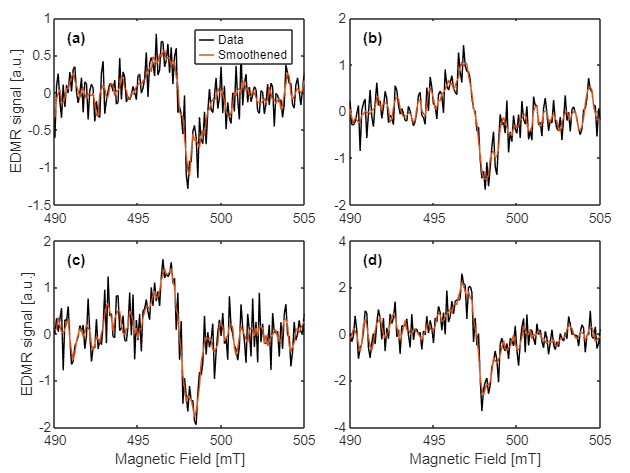

nm = 12; % Number of m parameters for datasmooth
mArray = (12 - nm/2):(12 + nm/2);
yS = repmat( ...
    {repmat(yRaw(:, 1), [1, nm])}, ...
    [1, ncw]);
% [dPay, Pay] = deal(zeros(nm, 1)); payFun = @(yS, yRaw) sum((yS -
% yRaw).^2)/numel(yS);+
for icw = 1:ncw
    xRaw_ = xRaw(:, icw);
    yRaw_ = yRaw(:, icw);
    figure('Visible', 'off')
    plot(xRaw_, yRaw_, 'DisplayName', 'raw')
    hold on
    for im = 1:nm
        yS{icw}(:, im) = datasmooth(yRaw_, mArray(im), 'savgol');
        plot(xRaw_, yS{icw}(:, im), 'DisplayName', sprintf('%i', mArray(im)))
%         Pay(im) = payFun(yS{icw}(:, im), yRaw_);
%         if im > 1
%             dPay(im) = Pay(im) - Pay(im - 1);
%         end
    end
    legend
end
M_PARAMS = 3;
y = datasmooth(yRaw, M_PARAMS, 'savgol');
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    plot(xRaw(:, icw), yRaw(:, icw), 'Color', 'black')
    hold on
    plot(xRaw(:, icw), y(:, icw));
end
lgd = legendFirstTile(tL, {'Data', 'Smoothened'});
annotateSubplotId(tL)
labelAxesFig(tL, 'Magnetic Field [mT]', 'EDMR signal [a.u.]')

#### Spin systems

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [0. 1.38], ...
    Nucs = 'Si', A = [151 269]);
VaryDb = struct( ...
    lw = 0);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [0. 0.54], ...
    weight = 0.3);
VaryV = struct( ...
    lw = 0, ...
    weight = SysV.weight);

Exp.mwFreq = 14; % GHz
Exp.nPoints = numel(xRaw_);
ExpVary.mwFreq = 1;

Sys = {SysDb, SysV};
SysVary = {VaryDb, VaryV};

## Field offset for fit with two spin systems

*pepperFieldOffset *does not work with more than 1 spin system. Correction is done shifting the magnetic field array, then the shift is checked again after the fitting.

Since we noticed that one spin system fits the data well, below I fit with *peppeFieldOffset* directly and then correct the data after the fit.

% Sys = SysDb;
% Vary = VaryDb;

wbar = waitbar(0, 'Performing least-square fitting', ...
    'Name', 'esfit in progress');
for icw = 1:ncw
    xRaw_ = xRaw(:, icw); y_ = y(:, icw);
    Exp.Range = [min(xRaw_) max(xRaw_)];
    Exp.mwFreq = 14;
    Fit_ = esfit(y_, @pepper, {Sys, Exp}, {SysVary, ExpVary});
    if icw == 1
        Fit = repmat({Fit_}, 1, ncw);
    else
        Fit{icw} = Fit_;
    end
    % Update B with the best value of Field Offset
    % x(:, icw) = xRaw(:, icw) - Fit(icw).pfit(2);
    waitbar(icw/ncw, wbar)
end

-- esfit ------------------------------------------------
Data size:                [151, 1]
Model function name:      pepper
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
         Check field range and spectrometer frequency.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   1: value 2.89068e-01   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
iteration   2: valu

delete(wbar)

mwFit = zeros(1, ncw);
for iFit = 1:ncw
    mwFit(iFit) = Fit{1, iFit}.pfit(2);
end
BOffset = mhz2mt((Exp.mwFreq - mean(mwFit))*1000, 2.0075) % 2.0075 is a compromise between 2.0055 and 2.01

BOffset = 1.2430

x = xRaw + BOffset;


Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
saveStr = input('Export data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    cwStruct = cw.cwStruct;
    save([Opt.SFolder, '\fit_chip_noLwFit'], 'x', 'y', 'cwStruct', 'Fit');
    % exportgraphics(gcf, [Opt.SFolder, '/2022-06-17 cwEDMR forward bias.png'])
else
    disp('Data not exported')
end

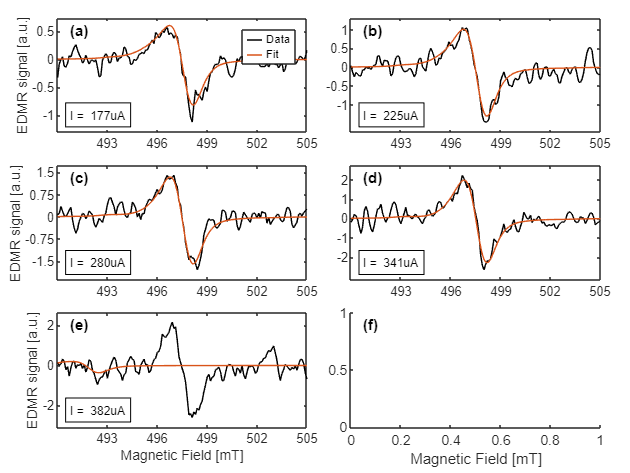

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    x_ = x(:, icw); y_ = y(:, icw); yFit_ = Fit(icw).fit;
    h(1) = plot(x_, y_, 'Color', 'black');
    hold on
    h(2) = plot(x_, yFit_);

    xticks(493:3:508);
    xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));

    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
end
nexttile(2); yticks(-1:.5:1);
nexttile(3); yticks(-1.5:.75:1.5);
nexttile(4); yticks(-2:1:2);
annotateSubplotId(tL)
labelAxesFig(tL, "Magnetic Field [mT]", "EDMR signal [a.u.]")
lgd = legendFirstTile(tL, {'Data', 'Fit'}, h);


Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, "fit chip", "pdf", 'fit')

Graphics not exported


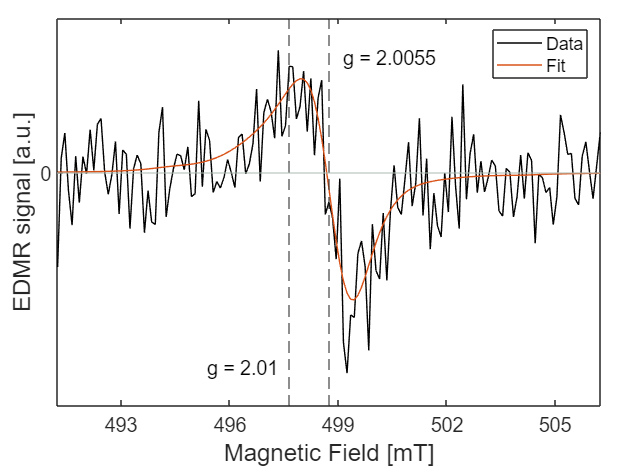

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = "D:\Profile\qse\Files\_EDMRoC pinSC\Images";

load([Opt.LFolder, '\fit_chip_noLwFit']);
cw = load([Opt.LFolder, '\cwEDMR_chip.mat']);
xRaw = cw.x; yRaw = cw.y;

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
icw = 1; % Vbias = 1.1 V
grayC = '#b2beb5';
x_ = x(:, icw); y_ = datasmooth(yRaw(:, icw), 1, 'savgol'); yFit_ = Fit{1, icw}.fit;
ax = nexttile(1);
h(1) = plot(x_, y_, Color = 'black', DisplayName = 'Data');
hold on
h(2) = plot(x_, yFit_, DisplayName = 'Fit');

h(3) = xline(mhz2mt(14*1000, 2.0055), '--');
h(4) = xline(mhz2mt(14*1000, 2.01), '--');
h(5) = yline(0, 'Color', grayC);

xticks(493:3:508); yticks(0);
xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));

Label3 = "g = 2.0055";
text(0.525, 0.9, Label3, 'Units', 'normalized', ...
    'FontSize', 13);
Label4 = "g = 2.01";
text(0.275, 0.1, Label4, 'Units', 'normalized', ...
    'FontSize', 13);
labelAxesFig(tL, "Magnetic Field [mT]", "EDMR signal [a.u.]")
legend([h(1) h(2)])

exportFig(gcf, Opt.SFolder, "_fit chip m1", "pdf");

Graphics not exported


exportFig(gcf, Opt.SFolder, "_fit chip m1", "png");

Graphics not exported


figure()
plot(x, y, x, scaleY(cumtrapz(y), y))
[~, id] = max(cumtrapz(y))
xline(x(id))
hold on
xnew = x(id:end);
ynew = cumtrapz(y(1:id));
ynewnew = flip(ynew);

plot(xnew, scaleY(ynewnew, y))

Exp.Range = [min(x) max(x)];
Sys = SysDb;
Vary = VaryDb;
Fit1comp = esfit(y, @pepper, {Sys, Exp}, {Vary});

## ppAmp vs Vbias

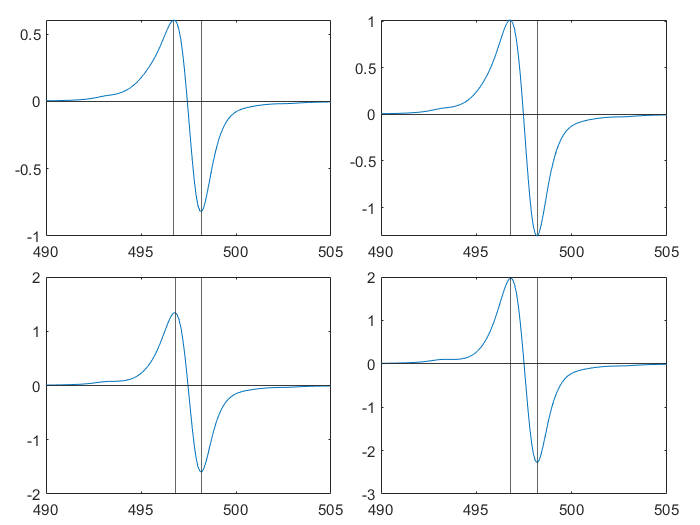

ans = 7.1979e-10

ans = 1.5124e-10

ans = 2.6693e-10

ans = 1.2035e-09

ans = 2.6563e-10

ans = 3.9026e-10

ans = 1.5983e-09

ans = 2.5284e-10

ans = 4.5738e-10

ans = 2.3524e-09

ans = 4.0163e-10

ans = 6.4167e-10

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_chip']);
[~, ncw] = size(x);

[ppAmp, yMax, yMin, xMax, xMin, noiseStdev1, noiseStdev3] = deal(zeros(1, ncw));

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
Idc = [177 225 280 341 382];
for icw = 1:ncw - 1
    x_ = x(:, icw); y_ = y(:, icw); yRaw_ = cwStruct(icw).y;
    yFit_ = Fit(icw).fit;
    [ppAmp(icw), yMax(icw), yMin(icw), xMax(icw), xMin(icw)] = getPeakToPeakAmp(x_, auToDIOverI(yFit_, Idc(icw), 1.2e6));
    noiseRange = [min(x_), 492; 503, max(x_)];
    [~, ~, noiseStdev3(icw)] = getSNR(x_, y_, noiseRange);
    noiseStdev3(icw) = auToDIOverI(noiseStdev3(icw), Idc(icw), 1.2e6);
    [~, ~, noiseStdev1(icw)] = getSNR(x_, yRaw_, noiseRange);
    noiseStdev1(icw) = auToDIOverI(noiseStdev1(icw), Idc(icw), 1.2e6);
    nexttile
    plot(x_, yFit_)
    hold on
    yline(yMax(icw)); yline(yMin(icw));
    xline(xMax(icw)); xline(xMin(icw));
end

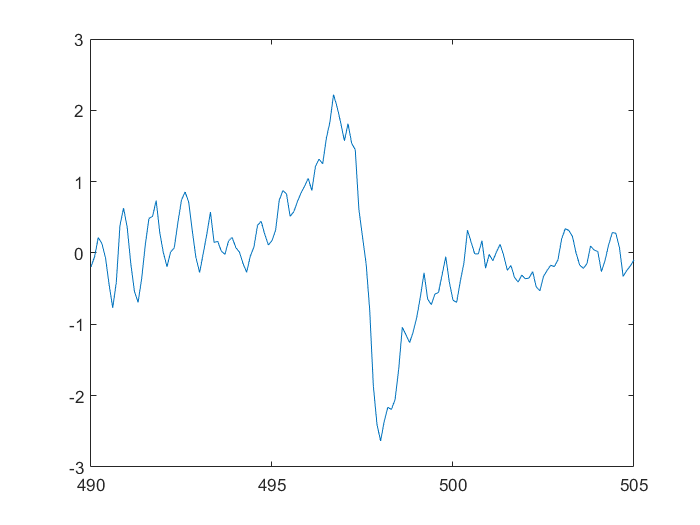

figure()
% plot(x_, auToDIOverI(y_, Idc(end), 1.2e6))
plot(x_, y_)

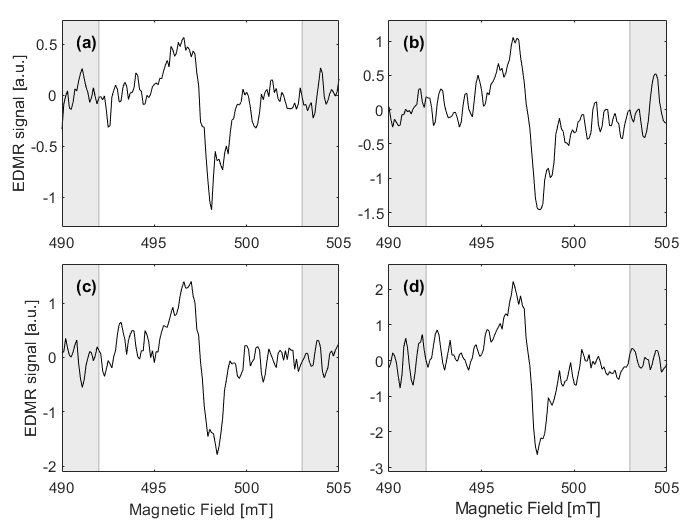


figure()
tL = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
gC = [0.4660 0.6740 0.1880]; % Green color
for icw = 1:ncw - 1
    nexttile
    x_ = x(:, icw); y_ = y(:, icw); yRaw_ = cwStruct(icw).y;
    plot(x_, y_, 'Color', [0 0 0])
    hold on
    rectangle('Position', [0 -50 noiseRange(1, 2) 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    rectangle('Position', [noiseRange(2, 1) -50 200 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    
    h = get(gca, 'Children');
    set(gca,'Children',[h(3) h(1) h(2)])
    set(gca, "Layer", "top")
    
    % xticks(337:2.5:347); yticks(-1:0.5:1);
    xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));
end
annotateSubplotId(tL)
labelAxesFig(tL, 'Magnetic Field [mT]', 'EDMR signal [a.u.]')

figure()
plot([1.2, 1.3, 1.4, 1.5, 1.6], ppAmp) % Last datapoint will be omitted

## Figure amplitude pp vs Vbias

Expected linear behavior.

Last datapoint (Vbias = 1.6 V) is taken out.

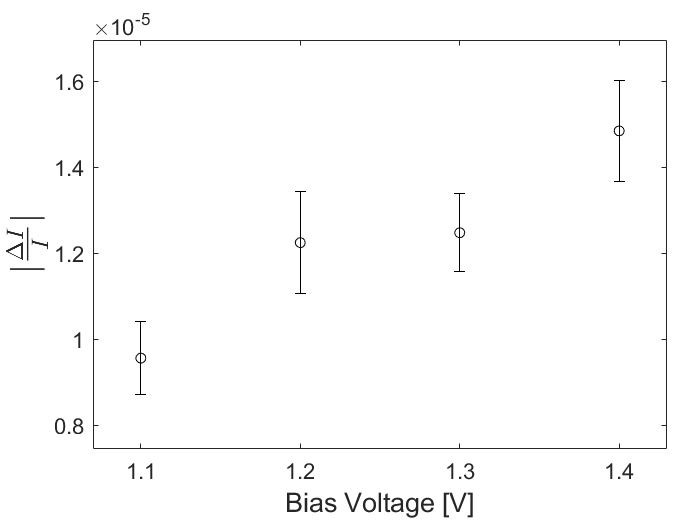

f = figure();
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');

ax = nexttile(1);
Vbias = 1.1:0.1:1.4; % Vbias is shifted by 1, as we observed a constant shift during the experiment
ppAmpCut = ppAmp(1:end - 1);
h(1) = errorbar(Vbias, ppAmpCut, noiseStdev3(1:4), 'o', 'Color', 'black');

xticks(Vbias); 
xlim(setAxLim(Vbias, 0.1)); ylim(setAxLim(ppAmpCut, 0.4));

labelAxesFig(tL, "Bias Voltage [V]", '$| \frac{\Delta I}{I} |$')
yticks((0.8:0.2:1.6)*1e-5);
ax.YLabel.FontSize = ax.YLabel.FontSize + 5;

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(f, Opt.SFolder, "_ppAmp noLwFit stdev3", ".pdf", 'ppAmp vs Vbias');
exportFig(f, Opt.SFolder, "_ppAmp noLwFit stdev3", "png", 'ppAmp vs Vbias');

function y = auToDIOverI(y, I0, ampFactor)
    % 1000 because lockin is in mV and not in V
    % 0.7 is the RMS factor
    % ampFactor should be in Ohm = V/A
    y = y/(1000*0.7*ampFactor); % A
    max(y)
    y = y./(I0*1e-6); % 1e-6 to convert I0 from uA to A
end